`clc
clear


%Set up directory and paths
filePath = matlab.desktop.editor.getActiveFilename;
folderPath = erase(filePath,'data_analysis.mlx');
cd(folderPath)
cd(folderPath)
cd ..
addpath("data/")
addpath("input/")
addpath("src/")

cd ./data

%Read database file
material_database_mat_file = load("../input/microstructures_object_array_final.mat");
material_database = material_database_mat_file.microstructure_array;
material_database_table = struct2table(material_database)

material_database_table = 75×27 table
    grain_size    lath_thickness    f_alpha    f_beta    f_mart       folder        yield_stress_ZZ        Ez          Pxz      yield_stress_XX        Ex          Pzx        Pyx      yield_stress_XY       Gxy        yield_stress_XZ       Gxz         yld_ref       R11       R22      R33      R12        R13        R23      Elastic_Parameters                       Yield_stresses                       Hill_Parameters
    __________    ______________    _______<

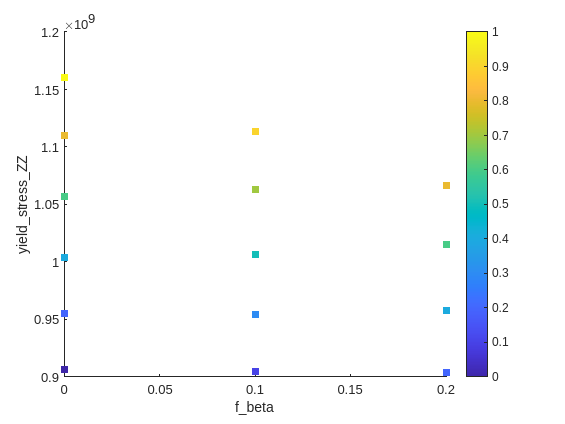

figure()
yieldZvsBeta = scatter(material_database_table,"f_beta","yield_stress_ZZ","filled");

yieldZvsBeta.Marker = "sq";
yieldZvsBeta.MarkerFaceColor = "flat";
yieldZvsBeta.ColorVariable = "f_mart";
colorbar


figure()
yieldZvsBeta = scatter(material_database_table,"f_alpha","Exy","filled");

Error using scatter
The variable 'Exy' was not found.


yieldZvsBeta.Marker = "sq";
yieldZvsBeta.MarkerFaceColor = "flat";

yieldZvsBeta.ColorVariable = "f_mart";
colorbar

figure()
yieldZvsBeta = scatter(material_database_table,"f_mart","Ex","filled");

yieldZvsBeta.Marker = "sq";
yieldZvsBeta.MarkerFaceColor = "flat";

yieldZvsBeta.ColorVariable = "f_mart";

% % Vary the transparency
% yieldZvsBeta.MarkerFaceAlpha = "flat";
% yieldZvsBeta.AlphaVariable = "f_beta";

colorbar


% %Loop over all microstructures
% 
% i_alpha_0=1;
% i_beta_0=1;
% i_mart_0=1;
% 
% for n = 1:1:length(material_database)
%     
%     microstructure = material_database(n);
%     
%     if microstructure.f_alpha == 0.0
%         yield_ZZ_for_f_alpha_0(i_alpha_0) = microstructure.Yield_stresses(1);
%         f_beta_for_f_alpha_0(i_alpha_0) = microstructure.f_beta;
%         f_mart_for_f_alpha_0(i_alpha_0) = microstructure.f_mart;
%         i_alpha_0=i_alpha_0+1;
%     end
% 
%     if microstructure.f_beta == 0.
%         yield_ZZ_for_f_beta_0(i_beta_0) = microstructure.Yield_stresses(1);
%         f_mart_for_f_beta_0(i_beta_0) = microstructure.f_mart;
%         f_alpha_for_f_beta_0(i_beta_0) = microstructure.f_alpha;
%         i_beta_0=i_beta_0+1;
%     end
% 
%     if microstructure.f_mart == 0.
%         yield_ZZ_for_f_mart_0(i_mart_0) = microstructure.Yield_stresses(1);
%         f_beta_for_f_mart_0(i_mart_0) = microstructure.f_beta;
%         f_alpha_for_f_mart_0(i_mart_0) = microstructure.f_alpha;
%         i_mart_0=i_mart_0+1;
%     end
% 
% end

## Figures

% 
% 
% figure()
% plot(f_beta_for_f_alpha_0,yield_ZZ_for_f_alpha_0,"*")
% title('yield Z vs \beta for \alpha = 0')
% 
% figure()
% plot(f_mart_for_f_alpha_0,yield_ZZ_for_f_alpha_0,"*")
% title("yield Z vs \alpha ' for \alpha = 0")
% 
% figure()
% plot(f_mart_for_f_beta_0,yield_ZZ_for_f_beta_0,"*")
% title("yield Z vs \alpha ' for \beta = 0")
% 
% figure()
% plot(f_alpha_for_f_beta_0,yield_ZZ_for_f_beta_0,"*")
% title("yield vs \alpha for \beta = 0")